clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[2.626;6.924;24.665];
u31=[0.104;0.267;0.958];
r2=[2.440;11.449;17.249];
u32=[0.120;0.550;0.826];
r3=[7.518;0.711;21.079];
u33=[-0.104;0.267;-0.958];
r4=[7.512;7.189;13.247];
u34=[0.120;-0.550;-0.826];
r5=[2.446;5.502;9.417];
u35=[-0.104;-0.267;0.958];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

hold on
axis([0 15 0 15]);
for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     5.9100    3.0000    1.0002


ans =     5.2700    3.3000    1.0003


ans =     4.8700    3.6000    1.0008


ans =     4.6000    3.9000    1.0019


ans =     4.4100    4.2000    1.0023


ans =     4.2700    4.5000    1.0021


ans =     4.1600    4.8000    1.0022


ans =     4.0700    5.1000    1.0029


ans =     4.0000    5.4000    1.0018


ans =     3.9400    5.7000    1.0010


ans =     3.8800    6.0000    1.0035


ans =     3.8400    6.3000    1.0003


ans =     3.7900    6.6000    1.0032


ans =     3.7500    6.9000    1.0035


ans =     3.7200    7.2000    1.0007


ans =     3.6800    7.5000    1.0031


ans =     3.6500    7.8000    1.0019


ans =     3.6200    8.1000    1.0012


ans =     3.5900    8.4000    1.0010


ans =     3.5600    8.7000    1.0010


ans =     3.5300    9.0000    1.0013


ans =     3.5000    9.3000    1.0017


ans =     3.4700    9.6000    1.0021


ans =     3.4400    9.9000    1.0026


ans =     3.4100   10.2000    1.0030


ans =     3.3800   10.5000    1.0033


ans =     3.3500   10.8000    1.0035


ans =     3.3200   11.1000    1.0035


ans =     3.2900   11.4000    1.0033


ans =     3.2600   11.7000    1.0029


ans =     3.2300   12.0000    1.0022


ans =     3.2000   12.3000    1.0013


ans =     3.1700   12.6000    1.0001


ans =     3.1300   12.9000    1.0030


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     5.5100    2.0000    1.0020


ans =     5.1800    2.3000    1.0018


ans =     4.9400    2.6000    1.0011


ans =     4.7600    2.9000    1.0022


ans =     4.6300    3.2000    1.0016


ans =     4.5300    3.5000    1.0012


ans =     4.4500    3.8000    1.0010


ans =     4.3800    4.1000    1.0026


ans =     4.3300    4.4000    1.0005


ans =     4.2800    4.7000    1.0012


ans =     4.2400    5.0000    1.0001


ans =     4.2000    5.3000    1.0006


ans =     4.1600    5.6000    1.0023


ans =     4.1300    5.9000    1.0007


ans =     4.0900    6.2000    1.0041


ans =     4.0600    6.5000    1.0038


ans = 1×3
    4.0300    6.8000    1.0038


ans = 1×3
    4.0000    7.1000    1.0041


ans = 1×3
    3.9800    7.4000    1.0004


ans = 1×3
    3.9500    7.7000    1.0011


ans = 1×3
    3.9200    8.0000    1.0019


ans = 1×3
    3.8900    8.3000    1.0028


ans = 1×3
    3.8600    8.6000    1.0038


ans = 1×3
    3.8400    8.9000    1.0005


ans = 1×3
    3.8100    9.2000    1.0016


ans = 1×3
    3.7800    9.5000    1.0028


ans = 1×3
    3.7500    9.8000    1.0040


ans = 1×3
    3.7300   10.1000    1.0009


ans = 1×3
    3.7000   10.4000    1.0023


ans = 1×3
    3.6700   10.7000    1.0037


ans = 1×3
    3.6500   11.0000    1.0009


ans = 1×3
    3.6200   11.3000    1.0025


ans = 1×3
    3.5900   11.6000    1.0043


ans = 1×3
    3.5700   11.9000    1.0018


ans = 1×3
    3.5400   12.2000    1.0039


ans = 1×3
    3.5200   12.5000    1.0017


ans = 1×3
    3.4900   12.8000    1.0041


plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')

for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    7.5700    2.0000    1.0000


ans = 1×3
    7.3800    2.3000    1.0017


ans = 1×3
    7.2300    2.6000    1.0002


ans = 1×3
    7.0900    2.9000    1.0016


ans = 1×3
    6.9800    3.2000    1.0004


ans = 1×3
    6.8800    3.5000    1.0004


ans = 1×3
    6.7900    3.8000    1.0007


ans = 1×3
    6.7100    4.1000    1.0007


ans = 1×3
    6.6300    4.4000    1.0023


ans = 1×3
    6.5600    4.7000    1.0025


ans = 1×3
    6.5000    5.0000    1.0008


ans = 1×3
    6.4300    5.3000    1.0023


ans = 1×3
    6.3700    5.6000    1.0013


ans = 1×3
    6.3100    5.9000    1.0005


ans = 1×3
    6.2400    6.2000    1.0023


ans = 1×3
    6.1800    6.5000    1.0013


ans = 1×3
    6.1200    6.8000    1.0001


ans = 1×3
    6.0500    7.1000    1.0012


ans = 1×3
    5.9800    7.4000    1.0020


ans = 1×3
    5.9100    7.7000    1.0024


ans = 1×3
    5.8400    8.0000    1.0024


ans = 1×3
    5.7700    8.3000    1.0020


ans = 1×3
    5.7000    8.6000    1.0012


ans = 1×3
    5.6300    8.9000    1.0000


ans = 1×3
    5.5500    9.2000    1.0010


ans = 1×3
    5.4700    9.5000    1.0016


ans = 1×3
    5.3900    9.8000    1.0018


ans = 1×3
    5.3100   10.1000    1.0017


ans = 1×3
    5.2300   10.4000    1.0013


ans = 1×3
    5.1500   10.7000    1.0006


ans = 1×3
    5.0600   11.0000    1.0022


ans = 1×3
    4.9800   11.3000    1.0012


ans = 1×3
    4.9000   11.6000    1.0002


ans = 1×3
    4.8100   11.9000    1.0015


ans = 1×3
    4.7300   12.2000    1.0005


ans = 1×3
    4.6400   12.5000    1.0020


ans = 1×3
    4.5600   12.8000    1.0013


plot(x3,y3,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','2-3')


for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    6.8500    3.0000    1.0006


ans = 1×3
    5.0700    3.3000    1.0004


ans = 1×3
    4.2600    3.6000    1.0018


ans = 1×3
    3.8300    3.9000    1.0011


ans = 1×3
    3.5600    4.2000    1.0009


ans = 1×3
    3.3700    4.5000    1.0026


ans = 1×3
    3.2400    4.8000    1.0008


ans = 1×3
    3.1300    5.1000    1.0036


ans = 1×3
    3.0500    5.4000    1.0028


ans = 1×3
    2.9800    5.7000    1.0042


ans = 1×3
    2.9300    6.0000    1.0010


ans = 1×3
    2.8800    6.3000    1.0017


ans = 1×3
    2.8400    6.6000    1.0002


ans = 1×3
    2.8000    6.9000    1.0012


ans = 1×3
    2.7600    7.2000    1.0042


ans = 1×3
    2.7300    7.5000    1.0032


ans = 1×3
    2.7000    7.8000    1.0034


ans = 1×3
    2.6700    8.1000    1.0047


ans = 1×3
    2.6500    8.4000    1.0008


ans = 1×3
    2.6200    8.7000    1.0034


ans = 1×3
    2.6000    9.0000    1.0005


ans = 1×3
    2.5700    9.3000    1.0041


ans = 1×3
    2.5500    9.6000    1.0018


ans = 1×3
    2.5200    9.9000    1.0059


ans = 1×3
    2.5000   10.2000    1.0040


ans = 1×3
    2.4800   10.5000    1.0021


ans = 1×3
    2.4600   10.8000    1.0003


ans = 1×3
    2.4300   11.1000    1.0046


ans = 1×3
    2.4100   11.4000    1.0027


ans = 1×3
    2.3900   11.7000    1.0008


ans = 1×3
    2.3600   12.0000    1.0048


ans = 1×3
    2.3400   12.3000    1.0026


ans = 1×3
    2.3200   12.6000    1.0003


ans = 1×3
    2.2900   12.9000    1.0038


plot(x4,y4,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','2-4')


for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    8.8700    3.0000    1.0010


ans = 1×3
    8.3500    3.3000    1.0013


ans = 1×3
    7.7900    3.6000    1.0005


ans = 1×3
    7.1700    3.9000    1.0011


ans = 1×3
    6.5100    4.2000    1.0009


ans = 1×3
    5.8300    4.5000    1.0002


ans = 1×3
    5.1600    4.8000    1.0003


ans = 1×3
    4.5600    5.1000    1.0001


ans = 1×3
    4.0500    5.4000    1.0011


ans = 1×3
    3.6400    5.7000    1.0013


ans = 1×3
    3.3100    6.0000    1.0001


ans = 1×3
    3.0200    6.3000    1.0012


ans = 1×3
    2.7700    6.6000    1.0014


ans = 1×3
    2.5500    6.9000    1.0001


ans = 1×3
    2.3400    7.2000    1.0009


ans = 1×3
    2.1400    7.5000    1.0028


ans = 1×3
    1.9600    7.8000    1.0024


ans = 1×3
    1.7900    8.1000    1.0021


ans = 1×3
    1.6300    8.4000    1.0024


ans = 1×3
    1.4900    8.7000    1.0002


ans = 1×3
    1.3500    9.0000    1.0037


ans = 1×3
    1.2400    9.3000    1.0026


ans = 1×3
    1.1500    9.6000    1.0009


ans = 1×3
    1.0700    9.9000    1.0042


ans = 1×3
    1.0100   10.2000    1.0061


ans = 1×3
    0.9700   10.5000    1.0023


ans = 1×3
    0.9300   10.8000    1.0065


ans = 1×3
    0.9000   11.1000    1.0083


ans = 1×3
    0.8800   11.4000    1.0046


ans = 1×3
    0.8600   11.7000    1.0051


ans = 1×3
    0.8400   12.0000    1.0098


ans = 1×3
    0.8300   12.3000    1.0038


ans = 1×3
    0.8200   12.6000    1.0001


ans = 1×3
    0.8000   12.9000    1.0146


plot(x5,y5,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5,'DisplayName','2-5')


for R3=1:0.3:13 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    4.6800    1.0000    1.0019


ans = 1×3
    4.4700    1.3000    1.0017


ans = 1×3
    4.2300    1.6000    1.0036


ans = 1×3
    4.0000    1.9000    1.0013


ans = 1×3
    3.7800    2.2000    1.0028


ans = 1×3
    3.6000    2.5000    1.0020


ans = 1×3
    3.4500    2.8000    1.0036


ans = 1×3
    3.3400    3.1000    1.0016


ans = 1×3
    3.2500    3.4000    1.0019


ans = 1×3
    3.1800    3.7000    1.0018


ans = 1×3
    3.1200    4.0000    1.0040


ans = 1×3
    3.0800    4.3000    1.0013


ans = 1×3
    3.0400    4.6000    1.0031


ans = 1×3
    3.0100    4.9000    1.0029


ans = 1×3
    2.9800    5.2000    1.0056


ans = 1×3
    2.9600    5.5000    1.0047


ans = 1×3
    2.9400    5.8000    1.0057


ans = 1×3
    2.9300    6.1000    1.0021


ans = 1×3
    2.9100    6.4000    1.0060


ans = 1×3
    2.9000    6.7000    1.0048


ans = 1×3
    2.8900    7.0000    1.0044


ans = 1×3
    2.8800    7.3000    1.0048


ans = 1×3
    2.8700    7.6000    1.0059


ans = 1×3
    2.8700    7.9000    1.0011


ans = 1×3
    2.8600    8.2000    1.0032


ans = 1×3
    2.8500    8.5000    1.0059


ans = 1×3
    2.8500    8.8000    1.0023


ans = 1×3
    2.8400    9.1000    1.0057


ans = 1×3
    2.8400    9.4000    1.0026


ans = 1×3
    2.8300    9.7000    1.0066


ans = 1×3
    2.8300   10.0000    1.0041


ans = 1×3
    2.8300   10.3000    1.0017


ans = 1×3
    2.8200   10.6000    1.0064


ans = 1×3
    2.8200   10.9000    1.0044


ans = 1×3
    2.8200   11.2000    1.0025


ans = 1×3
    2.8200   11.5000    1.0008


ans = 1×3
    2.8100   11.8000    1.0061


ans = 1×3
    2.8100   12.1000    1.0046


ans = 1×3
    2.8100   12.4000    1.0032


ans = 1×3
    2.8100   12.7000    1.0019


ans = 1×3
    2.8100   13.0000    1.0007


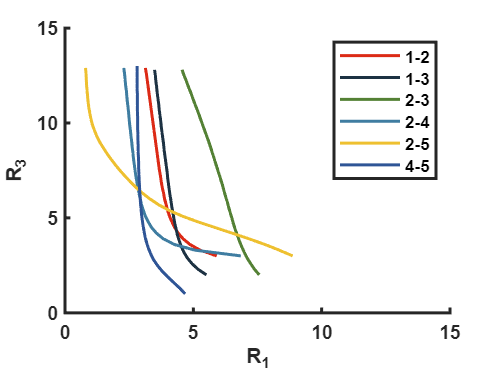

plot(x6,y6,'color',[47, 85, 151]/256, ...
    'LineWidth',1.5,'DisplayName','4-5')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');



hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
